# One Dimensional Brownian Motion

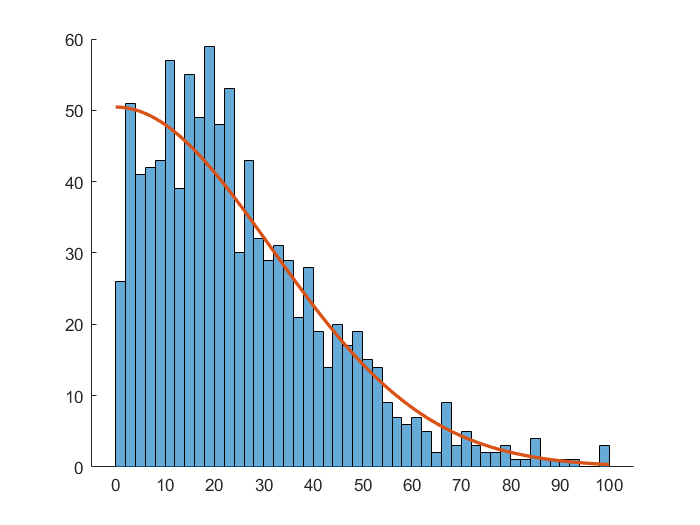

num_trials = 1000;
num_steps = 1000;
random_steps = 2*randi(2,num_steps,num_trials)-3; % num_steps x num_trials array of -1s and 1s
step_sums = sum(random_steps,1);
figure
hold on
histogram(abs(step_sums),'BinEdges',0:2:max(abs(step_sums))) % abs() to compute distance from center
plot(0:max(abs(step_sums)),2*num_trials*exp(-power(0:max(abs(step_sums)),2)/2/num_steps)*sqrt(2/pi/num_steps),'LineWidth',2)

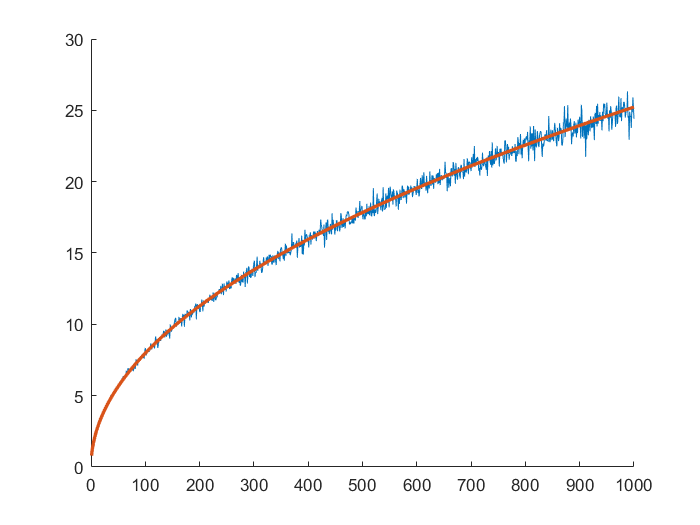

% Extra factor of two comes from the fact that our step size is 2

num_trials = 1000;
step_range = 1:1000;
average_dist = zeros(1,length(step_range));
for ii = step_range
    random_steps = 2*randi(2,ii,num_trials)-3;
    step_sums = sum(random_steps,1);
    average_dist(ii) = mean(abs(step_sums)); % abs() to compute distance from center
end
    
figure
hold on
plot(step_range,average_dist)
plot(step_range,sqrt(step_range)*sqrt(2/pi),'LineWidth',2)